# Dendrite DC Analysis Workbook

In this workbook I will develop an algorithm for calculating the DC operating point of a dendrite, given a vector of resistances for each edge of the graph.

I want to get an algorithm working before I optimize anything. So I'm going to loop through all of the nodes and build a up a big matrix that can be solved to find the voltages at each node. Future iterations may develop an algorithm that builds the smallest matrix needed to be solved, but I'll cross that bridge when I come to it.

## Load Dendrite

First just load the dendrite data.

clear
load('dendrites10.mat');
d = dendrite(trees{16}.dA, trees{16}.X, trees{16}.Y, []);
%d = d.ladder
d.dA

ans =      0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     1     0     0     0     0     0     0     0     0


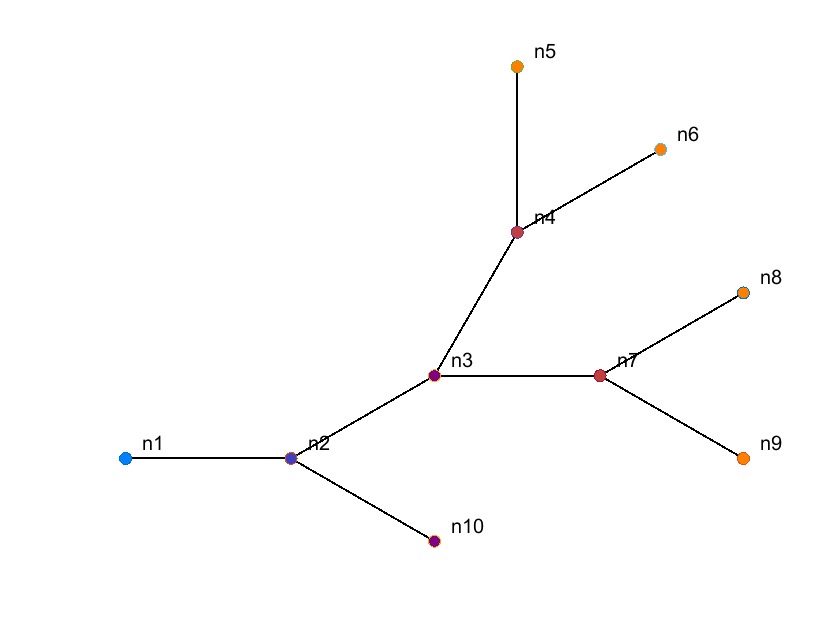

Current plot held


d.plot(d.branchOrder, 'n');

## Resistances

I want to compare this to the ones we've already done in LTSPICE, so I should use the same R values. 

Each edge has a unique end node. So I will set the resistance based on the index of the end node of the edge. I.e. The resistor between n1 and n2 will be stored in R(2)

R = 100*2.^(d.branchOrder-1);
R(1) =0

R =      0
   100
   200
   400
   800
   800
   400
   800
   800
   200


## NodalAnalysis

## Terminations

This approach is based on Loop Analysis. I will do a for loop to move between resistors and set each of the sums of the voltage drops equal to a known value. I can then solve for the currents in each branch, and therefore find the voltage at each node.

I'll start at each termination node, then follow the dA to trace it back to the GND point. This voltage drop should be equal to Vdd.

terminations = find(d.BCT==0)

terminations =      5     6     8     9    10



RMatrix = zeros(d.nodes-1, d.nodes);
V = [];
Vdd = 10;

for i =1:length(terminations)
    startNode= terminations(i);
    currentNode = startNode;
    drops = zeros(1,d.nodes);
    
    while(currentNode ~= 1)
        nextNode= find(d.dA(currentNode,:)); %Find the node that feeds the current node.
        drops(currentNode) = R(currentNode);
        
        
        currentNode = nextNode;
    end
    
    RMatrix(i,:) = drops;
    V =[V;Vdd];
end

## Branches

Now fill out the RMatrix with each of the spots where the currents should sum together. At each branching point, the currents exiting should be equal to the current entering. This same approach works for continuations. So I'll just include those here too.

branches = find(d.BCT==2|d.BCT==1);

for j = 1:length(branches)
    RMatrix(i+j,:) = d.dA(:,branches(j))';
    RMatrix(i+j,branches(j)) = -1;
    V = [V; 0];
end


## Solve the system

currents = RMatrix\V

currents =     0.0400
    0.0400
    0.0100
    0.0050
    0.0025
    0.0025
    0.0050
    0.0025
    0.0025
    0.0300



Vdrops = currents.*R

Vdrops =          0
    4.0000
    2.0000
    2.0000
    2.0000
    2.0000
    2.0000
    2.0000
    2.0000
    6.0000


## Solve for Node Voltages wrt GND

My Vdrops vector just tells the voltage drops across each resistor, but I want to know the voltage with respect to Ground of each node. I'm sure there's a more direct method, but I'm pretty far along in this mostly ad hoc approach, so I'll just finish it this way and optimize later.

Just build a matrix from the dA that has rows indicating the voltage drops that sum to give that node's votage. Scroll through each node and add a 1 to the matrix for each Vdrop that adds to the voltage of that node.

dropMat = zeros(d.nodes)

dropMat =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



for i = 1:d.nodes
    currentNode = i;
    drops = zeros(1,d.nodes);
    
    while(currentNode ~= 1)
        nextNode= find(d.dA(currentNode,:)); %Find the node that feeds the current node.
        drops(currentNode) = 1;
        
        
        currentNode = nextNode;
    end
    
    dropMat(i,:) = drops;
end

nodeV = dropMat*Vdrops

nodeV =      0
     4
     6
     8
    10
    10
     8
    10
    10
    10


## Future Revisions

This approach cycles through all the nodes more than once to build 2 matrices. It would be simlpler just to cycle through all the nodes 1-d.nodes once and take care of everything in one go, rather than separating different loops for the branches, terminations, and continuations.

It would also be easy to allow for different voltages at each of the termination nodes.